## Load and split data

SpectroDatasetPath = fullfile('C:\Users\shunt\Documents\DATA\Work_HWU_Prof_Demuliez\WhiskyCounterfeit\ImageDataSet');
imds = imageDatastore(SpectroDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');
[imdsTrain,imdsTest, imdsValidation] = splitEachLabel(imds,0.7,0.15,0.15,'randomize');

## Modify final layers for transfer learning with Alexnet

net = alexnet;

layers = net.Layers;
layers(end-2) = fullyConnectedLayer(41);
layers(end) = classificationLayer;

## Specify Training Options

options = trainingOptions('adam', ...
    'InitialLearnRate',0.001, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',15, ...
    'MaxEpochs',60, ...
    'MiniBatchSize',30,...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'ValidationPatience',30, ...
    'Verbose',true, ...
    'Plots','training-progress');

## Train Network Using Training Data

net = trainNetwork(imdsTrain,layers,options);

Training on single GPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:05 |       10.00% |        4.88% |       8.0592 |       5.8444 |          0.0010 |


|       1 |          30 |       00:00:09 |       10.00% |        4.88% |       3.2884 |       3.5299 |          0.0010 |


|       1 |          50 |       00:00:11 |       20.00% |              |       2.7201 |              |          0.0010 |


|       1 |          60 |       00:00:12 |        6.67% |       19.54% |       4.3381 |       2.5902 |          0.0010 |


|       1 |          90 |       00:00:15 |       36.67% |       39.32% |       1.7182 |       1.7242 |          0.0010 |


|       1 |         100 |       00:00:16 |       36.67% |              |       1.7225 |              |          0.0010 |


|       1 |         120 |       00:00:19 |       43.33% |       58.97% |       1.7712 |       1.1329 |          0.0010 |


|       2 |         150 |       00:00:23 |       80.00% |       71.55% |       0.4028 |       0.7587 |          0.0010 |


|       2 |         180 |       00:00:26 |       60.00% |       67.03% |       1.1410 |       0.8544 |          0.0010 |


|       2 |         200 |       00:00:28 |       73.33% |              |       0.6534 |              |          0.0010 |


|       2 |         210 |       00:00:30 |       70.00% |       74.24% |       0.7647 |       0.7960 |          0.0010 |


|       2 |         240 |       00:00:34 |       76.67% |       80.46% |       0.6920 |       0.4374 |          0.0010 |


|       2 |         250 |       00:00:35 |       76.67% |              |       0.3973 |              |          0.0010 |


|       3 |         270 |       00:00:38 |       80.00% |       87.42% |       0.4712 |       0.3124 |          0.0010 |


|       3 |         300 |       00:00:42 |       80.00% |       83.39% |       0.5976 |       0.4426 |          0.0010 |


|       3 |         330 |       00:00:46 |       80.00% |       84.49% |       0.5447 |       0.4702 |          0.0010 |


|       3 |         350 |       00:00:48 |       80.00% |              |       0.4829 |              |          0.0010 |


|       3 |         360 |       00:00:50 |       83.33% |       80.95% |       0.4843 |       0.4143 |          0.0010 |


|       4 |         390 |       00:00:54 |       53.33% |       86.69% |       1.0153 |       0.3998 |          0.0010 |


|       4 |         400 |       00:00:55 |       63.33% |              |       1.1711 |              |          0.0010 |


|       4 |         420 |       00:00:58 |       80.00% |       87.55% |       0.4917 |       0.2694 |          0.0010 |


|       4 |         450 |       00:01:02 |       90.00% |       94.63% |       0.2715 |       0.1577 |          0.0010 |


|       4 |         480 |       00:01:06 |       83.33% |       89.26% |       0.3140 |       0.2260 |          0.0010 |


|       4 |         500 |       00:01:08 |       80.00% |              |       0.5487 |              |          0.0010 |


|       4 |         510 |       00:01:10 |       86.67% |       92.80% |       0.3230 |       0.2185 |          0.0010 |


|       5 |         540 |       00:01:14 |       96.67% |       95.24% |       0.1354 |       0.1616 |          0.0010 |


|       5 |         550 |       00:01:15 |       96.67% |              |       0.1464 |              |          0.0010 |


|       5 |         570 |       00:01:18 |       93.33% |       89.87% |       0.1568 |       0.4713 |          0.0010 |


|       5 |         600 |       00:01:22 |       86.67% |       85.84% |       0.4551 |       0.3283 |          0.0010 |


|       5 |         630 |       00:01:26 |       80.00% |       92.31% |       0.4396 |       0.2164 |          0.0010 |


|       6 |         650 |       00:01:28 |       83.33% |              |       0.4111 |              |          0.0010 |


|       6 |         660 |       00:01:30 |       90.00% |       88.89% |       0.2587 |       0.1902 |          0.0010 |


|       6 |         690 |       00:01:34 |       96.67% |       92.55% |       0.0986 |       0.1578 |          0.0010 |


|       6 |         700 |       00:01:35 |       96.67% |              |       0.1958 |              |          0.0010 |


|       6 |         720 |       00:01:38 |       80.00% |       90.60% |       0.5265 |       0.1720 |          0.0010 |


|       6 |         750 |       00:01:42 |       80.00% |       92.67% |       0.4284 |       0.1103 |          0.0010 |


|       7 |         780 |       00:01:46 |       90.00% |       92.43% |       0.2338 |       0.1670 |          0.0010 |


|       7 |         800 |       00:01:48 |       93.33% |              |       0.1097 |              |          0.0010 |


|       7 |         810 |       00:01:50 |       86.67% |       92.31% |       0.2674 |       0.1266 |          0.0010 |


|       7 |         840 |       00:01:54 |       76.67% |       88.64% |       0.4182 |       0.2143 |          0.0010 |


|       7 |         850 |       00:01:55 |       83.33% |              |       0.3238 |              |          0.0010 |


|       7 |         870 |       00:01:57 |       93.33% |       92.55% |       0.0809 |       0.1855 |          0.0010 |


|       7 |         900 |       00:02:01 |       90.00% |       94.38% |       0.1626 |       0.0964 |          0.0010 |


|       8 |         930 |       00:02:05 |      100.00% |       94.26% |       0.0437 |       0.1284 |          0.0010 |


|       8 |         950 |       00:02:07 |       93.33% |              |       0.1319 |              |          0.0010 |


|       8 |         960 |       00:02:09 |       90.00% |       94.51% |       0.6106 |       0.1887 |          0.0010 |


|       8 |         990 |       00:02:13 |       93.33% |       96.70% |       0.1571 |       0.0728 |          0.0010 |


|       8 |        1000 |       00:02:14 |       96.67% |              |       0.0659 |              |          0.0010 |


|       8 |        1020 |       00:02:17 |      100.00% |       93.41% |       0.0686 |       0.1664 |          0.0010 |


|       9 |        1050 |       00:02:21 |      100.00% |       92.19% |       0.0160 |       0.2085 |          0.0010 |


|       9 |        1080 |       00:02:25 |       80.00% |       92.67% |       0.3824 |       0.1854 |          0.0010 |


|       9 |        1100 |       00:02:27 |       96.67% |              |       0.0570 |              |          0.0010 |


|       9 |        1110 |       00:02:29 |       86.67% |       96.09% |       0.3121 |       0.0854 |          0.0010 |


|       9 |        1140 |       00:02:33 |       76.67% |       88.64% |       0.6334 |       0.5008 |          0.0010 |


|       9 |        1150 |       00:02:34 |       70.00% |              |       0.5864 |              |          0.0010 |


|      10 |        1170 |       00:02:37 |       90.00% |       97.31% |       0.2293 |       0.0565 |          0.0010 |


|      10 |        1200 |       00:02:41 |      100.00% |       94.63% |       0.0619 |       0.0866 |          0.0010 |


|      10 |        1230 |       00:02:45 |       96.67% |       94.02% |       0.1416 |       0.2194 |          0.0010 |


|      10 |        1250 |       00:02:47 |       93.33% |              |       0.1177 |              |          0.0010 |


|      10 |        1260 |       00:02:49 |       96.67% |       96.83% |       0.0960 |       0.0798 |          0.0010 |


|      10 |        1290 |       00:02:53 |       93.33% |       97.31% |       0.1309 |       0.0560 |          0.0010 |


|      11 |        1300 |       00:02:54 |       93.33% |              |       0.0829 |              |          0.0010 |


|      11 |        1320 |       00:02:57 |      100.00% |       97.44% |       0.0084 |       0.0613 |          0.0010 |


|      11 |        1350 |       00:03:01 |       96.67% |       97.56% |       0.0361 |       0.0372 |          0.0010 |


|      11 |        1380 |       00:03:05 |       73.33% |       87.30% |       0.6794 |       0.4986 |          0.0010 |


|      11 |        1400 |       00:03:07 |       76.67% |              |       0.7790 |              |          0.0010 |


|      11 |        1410 |       00:03:09 |       86.67% |       92.06% |       0.5978 |       0.3182 |          0.0010 |


|      12 |        1440 |       00:03:13 |       96.67% |       94.26% |       0.1206 |       0.1470 |          0.0010 |


|      12 |        1450 |       00:03:14 |       90.00% |              |       0.2706 |              |          0.0010 |


|      12 |        1470 |       00:03:17 |       93.33% |       97.31% |       0.1234 |       0.0582 |          0.0010 |


|      12 |        1500 |       00:03:21 |       76.67% |       94.51% |       0.4489 |       0.1095 |          0.0010 |


|      12 |        1530 |       00:03:25 |       96.67% |       96.09% |       0.0634 |       0.0724 |          0.0010 |


|      13 |        1550 |       00:03:27 |       96.67% |              |       0.0571 |              |          0.0010 |


|      13 |        1560 |       00:03:29 |       90.00% |       97.07% |       0.1292 |       0.0570 |          0.0010 |


|      13 |        1590 |       00:03:32 |       83.33% |       97.07% |       0.3288 |       0.0778 |          0.0010 |


|      13 |        1600 |       00:03:34 |       96.67% |              |       0.0631 |              |          0.0010 |


|      13 |        1620 |       00:03:36 |       96.67% |       96.34% |       0.1366 |       0.0734 |          0.0010 |


|      13 |        1650 |       00:03:40 |       93.33% |       97.07% |       0.0813 |       0.0585 |          0.0010 |


|      14 |        1680 |       00:03:44 |       93.33% |       95.12% |       0.1424 |       0.0840 |          0.0010 |


|      14 |        1700 |       00:03:46 |      100.00% |              |       0.0466 |              |          0.0010 |


|      14 |        1710 |       00:03:48 |       93.33% |       94.63% |       0.1397 |       0.0702 |          0.0010 |


|      14 |        1740 |       00:03:52 |       90.00% |       96.95% |       0.1529 |       0.0771 |          0.0010 |


|      14 |        1750 |       00:03:53 |       96.67% |              |       0.0861 |              |          0.0010 |


|      14 |        1770 |       00:03:56 |       96.67% |       97.31% |       0.0466 |       0.0467 |          0.0010 |


|      14 |        1800 |       00:04:00 |       96.67% |       97.19% |       0.1153 |       0.0636 |          0.0010 |


|      15 |        1830 |       00:04:04 |       80.00% |       90.84% |       1.0196 |       0.2959 |          0.0010 |


|      15 |        1850 |       00:04:06 |       86.67% |              |       0.2436 |              |          0.0010 |


|      15 |        1860 |       00:04:08 |       93.33% |       93.04% |       0.1526 |       0.1980 |          0.0010 |


|      15 |        1890 |       00:04:12 |       96.67% |       97.07% |       0.0536 |       0.0562 |          0.0010 |


|      15 |        1900 |       00:04:13 |       96.67% |              |       0.0709 |              |          0.0010 |


|      15 |        1920 |       00:04:16 |       93.33% |       97.44% |       0.2164 |       0.0431 |          0.0010 |


|      16 |        1950 |       00:04:20 |       93.33% |       97.44% |       0.0786 |       0.0391 |          0.0001 |


|      16 |        1980 |       00:04:24 |      100.00% |       97.44% |       0.0149 |       0.0402 |          0.0001 |


|      16 |        2000 |       00:04:26 |      100.00% |              |       0.0005 |              |          0.0001 |


|      16 |        2010 |       00:04:28 |      100.00% |       97.44% |       0.0173 |       0.0372 |          0.0001 |


|      16 |        2040 |       00:04:32 |       96.67% |       97.44% |       0.0276 |       0.0363 |          0.0001 |


|      16 |        2050 |       00:04:33 |      100.00% |              |       0.0132 |              |          0.0001 |


|      17 |        2070 |       00:04:35 |      100.00% |       97.44% |       0.0186 |       0.0367 |          0.0001 |


|      17 |        2100 |       00:04:39 |       93.33% |       97.56% |       0.0792 |       0.0367 |          0.0001 |


|      17 |        2130 |       00:04:43 |       96.67% |       97.56% |       0.0403 |       0.0355 |          0.0001 |


|      17 |        2150 |       00:04:45 |      100.00% |              |       0.0493 |              |          0.0001 |


|      17 |        2160 |       00:04:47 |      100.00% |       97.56% |       0.0235 |       0.0362 |          0.0001 |


|      17 |        2190 |       00:04:51 |       96.67% |       97.56% |       0.0298 |       0.0353 |          0.0001 |


|      18 |        2200 |       00:04:52 |       93.33% |              |       0.0747 |              |          0.0001 |


|      18 |        2220 |       00:04:55 |      100.00% |       97.56% |       0.0022 |       0.0352 |          0.0001 |


|      18 |        2250 |       00:04:59 |       90.00% |       97.56% |       0.0811 |       0.0354 |          0.0001 |


|      18 |        2280 |       00:05:03 |      100.00% |       97.56% |       0.0211 |       0.0351 |          0.0001 |


|      18 |        2300 |       00:05:05 |      100.00% |              |       0.0004 |              |          0.0001 |


|      18 |        2310 |       00:05:06 |      100.00% |       97.56% |       0.0041 |       0.0350 |          0.0001 |


|      19 |        2340 |       00:05:10 |       96.67% |       97.56% |       0.0256 |       0.0356 |          0.0001 |


|      19 |        2350 |       00:05:11 |       96.67% |              |       0.0435 |              |          0.0001 |


|      19 |        2370 |       00:05:14 |       90.00% |       97.56% |       0.0968 |       0.0356 |          0.0001 |


|      19 |        2400 |       00:05:18 |       96.67% |       97.44% |       0.0370 |       0.0360 |          0.0001 |


|      19 |        2430 |       00:05:22 |      100.00% |       97.44% |       0.0198 |       0.0354 |          0.0001 |


|      19 |        2450 |       00:05:24 |       96.67% |              |       0.0357 |              |          0.0001 |


|      20 |        2460 |       00:05:26 |       96.67% |       97.44% |       0.0424 |       0.0367 |          0.0001 |


|      20 |        2490 |       00:05:30 |       96.67% |       97.44% |       0.0694 |       0.0373 |          0.0001 |


|      20 |        2500 |       00:05:31 |      100.00% |              |       0.0003 |              |          0.0001 |


|      20 |        2520 |       00:05:34 |       93.33% |       97.44% |       0.1038 |       0.0376 |          0.0001 |


|      20 |        2550 |       00:05:37 |       96.67% |       97.44% |       0.0740 |       0.0358 |          0.0001 |


|      20 |        2580 |       00:05:41 |      100.00% |       97.56% |       0.0004 |       0.0353 |          0.0001 |


|      21 |        2600 |       00:05:43 |      100.00% |              |       0.0006 |              |          0.0001 |


|      21 |        2610 |       00:05:45 |      100.00% |       97.56% |       0.0016 |       0.0349 |          0.0001 |


|      21 |        2640 |       00:05:49 |      100.00% |       97.56% |       0.0226 |       0.0346 |          0.0001 |


|      21 |        2650 |       00:05:50 |       96.67% |              |       0.0275 |              |          0.0001 |


|      21 |        2670 |       00:05:53 |       96.67% |       97.56% |       0.0422 |       0.0352 |          0.0001 |


|      21 |        2700 |       00:05:57 |      100.00% |       97.56% |       0.0009 |       0.0345 |          0.0001 |


|      22 |        2730 |       00:06:01 |       93.33% |       97.44% |       0.0848 |       0.0352 |          0.0001 |


|      22 |        2750 |       00:06:03 |       96.67% |              |       0.0283 |              |          0.0001 |


|      22 |        2760 |       00:06:05 |      100.00% |       97.56% |       0.0002 |       0.0347 |          0.0001 |


|      22 |        2790 |       00:06:09 |       96.67% |       97.56% |       0.0537 |       0.0349 |          0.0001 |


|      22 |        2800 |       00:06:10 |       96.67% |              |       0.0356 |              |          0.0001 |


|      22 |        2820 |       00:06:13 |      100.00% |       97.56% |       0.0007 |       0.0359 |          0.0001 |


|      23 |        2850 |       00:06:17 |      100.00% |       97.56% |       0.0538 |       0.0345 |          0.0001 |


|      23 |        2880 |       00:06:21 |       96.67% |       97.56% |       0.0578 |       0.0349 |          0.0001 |


|      23 |        2900 |       00:06:23 |       96.67% |              |       0.0255 |              |          0.0001 |


|      23 |        2910 |       00:06:25 |      100.00% |       97.56% |       0.0178 |       0.0347 |          0.0001 |


|      23 |        2940 |       00:06:28 |       96.67% |       97.56% |       0.0341 |       0.0347 |          0.0001 |


|      23 |        2950 |       00:06:30 |      100.00% |              |       0.0001 |              |          0.0001 |


|      24 |        2970 |       00:06:32 |      100.00% |       97.56% |       0.0010 |       0.0346 |          0.0001 |


|      24 |        3000 |       00:06:36 |       96.67% |       97.56% |       0.0443 |       0.0346 |          0.0001 |


|      24 |        3030 |       00:06:40 |      100.00% |       97.56% |       0.0003 |       0.0346 |          0.0001 |


|      24 |        3050 |       00:06:42 |       96.67% |              |       0.0479 |              |          0.0001 |


|      24 |        3060 |       00:06:44 |      100.00% |       97.56% |       0.0003 |       0.0344 |          0.0001 |


|      24 |        3090 |       00:06:48 |      100.00% |       97.56% |       0.0394 |       0.0347 |          0.0001 |


|      25 |        3100 |       00:06:49 |       96.67% |              |       0.0427 |              |          0.0001 |


|      25 |        3120 |       00:06:52 |      100.00% |       97.56% |       0.0002 |       0.0344 |          0.0001 |


|      25 |        3150 |       00:06:56 |       96.67% |       97.56% |       0.0658 |       0.0343 |          0.0001 |


|      25 |        3180 |       00:07:00 |      100.00% |       97.56% |       0.0591 |       0.0343 |          0.0001 |


|      25 |        3200 |       00:07:02 |       96.67% |              |       0.0241 |              |          0.0001 |


|      25 |        3210 |       00:07:04 |      100.00% |       97.56% |       0.0214 |       0.0343 |          0.0001 |


|      26 |        3240 |       00:07:08 |       93.33% |       97.56% |       0.0621 |       0.0344 |          0.0001 |


|      26 |        3250 |       00:07:09 |       96.67% |              |       0.0522 |              |          0.0001 |


|      26 |        3270 |       00:07:12 |      100.00% |       97.56% |       0.0575 |       0.0344 |          0.0001 |


|      26 |        3300 |       00:07:16 |       93.33% |       97.56% |       0.0574 |       0.0343 |          0.0001 |


|      26 |        3330 |       00:07:20 |       93.33% |       97.56% |       0.1049 |       0.0343 |          0.0001 |


|      26 |        3350 |       00:07:22 |      100.00% |              |       0.0212 |              |          0.0001 |


|      27 |        3360 |       00:07:24 |       93.33% |       97.56% |       0.0683 |       0.0343 |          0.0001 |


|      27 |        3390 |       00:07:28 |       96.67% |       97.56% |       0.0297 |       0.0354 |          0.0001 |


|      27 |        3400 |       00:07:29 |      100.00% |              |       0.0004 |              |          0.0001 |


|      27 |        3420 |       00:07:32 |       96.67% |       97.56% |       0.0522 |       0.0341 |          0.0001 |


|      27 |        3450 |       00:07:36 |       96.67% |       97.56% |       0.0292 |       0.0341 |          0.0001 |


|      27 |        3480 |       00:07:40 |      100.00% |       97.56% |       0.0182 |       0.0342 |          0.0001 |


|      28 |        3500 |       00:07:42 |      100.00% |              |       0.0004 |              |          0.0001 |


|      28 |        3510 |       00:07:44 |       96.67% |       97.56% |       0.0438 |       0.0342 |          0.0001 |


|      28 |        3540 |       00:07:48 |      100.00% |       97.56% |       0.0200 |       0.0342 |          0.0001 |


|      28 |        3550 |       00:07:49 |      100.00% |              |       0.0281 |              |          0.0001 |


|      28 |        3570 |       00:07:52 |       96.67% |       97.56% |       0.0482 |       0.0344 |          0.0001 |


|      28 |        3600 |       00:07:56 |      100.00% |       97.56% |       0.0189 |       0.0342 |          0.0001 |


|      29 |        3630 |       00:08:00 |       93.33% |       97.56% |       0.0807 |       0.0346 |          0.0001 |


|      29 |        3650 |       00:08:02 |       93.33% |              |       0.0644 |              |          0.0001 |


|      29 |        3660 |       00:08:04 |       96.67% |       97.56% |       0.0475 |       0.0346 |          0.0001 |


|      29 |        3690 |       00:08:08 |      100.00% |       97.56% |       0.0147 |       0.0344 |          0.0001 |


|      29 |        3700 |       00:08:09 |       96.67% |              |       0.0407 |              |          0.0001 |


|      29 |        3720 |       00:08:12 |      100.00% |       97.56% |       0.0002 |       0.0345 |          0.0001 |


|      30 |        3750 |       00:08:16 |       90.00% |       97.56% |       0.0859 |       0.0341 |          0.0001 |


|      30 |        3780 |       00:08:20 |      100.00% |       97.56% |   9.4218e-05 |       0.0341 |          0.0001 |


|      30 |        3800 |       00:08:22 |      100.00% |              |       0.0213 |              |          0.0001 |


|      30 |        3810 |       00:08:24 |       96.67% |       97.56% |       0.0525 |       0.0342 |          0.0001 |


|      30 |        3840 |       00:08:28 |       86.67% |       97.56% |       0.1257 |       0.0345 |          0.0001 |


|      30 |        3850 |       00:08:30 |       96.67% |              |       0.0630 |              |          0.0001 |


|      30 |        3870 |       00:08:32 |      100.00% |       97.56% |       0.0210 |       0.0342 |          0.0001 |


|      31 |        3900 |       00:08:36 |       96.67% |       97.56% |       0.0639 |       0.0342 |      1.0000e-05 |


|      31 |        3930 |       00:08:40 |       96.67% |       97.56% |       0.0409 |       0.0341 |      1.0000e-05 |


|      31 |        3950 |       00:08:43 |       90.00% |              |       0.1315 |              |      1.0000e-05 |


|      31 |        3960 |       00:08:45 |      100.00% |       97.56% |       0.0001 |       0.0341 |      1.0000e-05 |


|      31 |        3990 |       00:08:49 |      100.00% |       97.56% |       0.0220 |       0.0341 |      1.0000e-05 |


|      32 |        4000 |       00:08:50 |       96.67% |              |       0.0261 |              |      1.0000e-05 |


|      32 |        4020 |       00:08:53 |       93.33% |       97.56% |       0.0631 |       0.0341 |      1.0000e-05 |


|      32 |        4050 |       00:08:57 |       96.67% |       97.56% |       0.0463 |       0.0341 |      1.0000e-05 |


|      32 |        4080 |       00:09:01 |       93.33% |       97.56% |       0.0880 |       0.0341 |      1.0000e-05 |


|      32 |        4100 |       00:09:03 |       96.67% |              |       0.0570 |              |      1.0000e-05 |


|      32 |        4110 |       00:09:06 |       96.67% |       97.56% |       0.0287 |       0.0341 |      1.0000e-05 |


|      33 |        4140 |       00:09:10 |       96.67% |       97.56% |       0.0468 |       0.0340 |      1.0000e-05 |


|      33 |        4150 |       00:09:11 |      100.00% |              |       0.0001 |              |      1.0000e-05 |


|      33 |        4170 |       00:09:13 |       96.67% |       97.56% |       0.0278 |       0.0341 |      1.0000e-05 |


|      33 |        4200 |       00:09:17 |       96.67% |       97.56% |       0.0256 |       0.0340 |      1.0000e-05 |


|      33 |        4230 |       00:09:21 |       96.67% |       97.56% |       0.0364 |       0.0340 |      1.0000e-05 |


|      33 |        4250 |       00:09:23 |       93.33% |              |       0.0555 |              |      1.0000e-05 |


|      34 |        4260 |       00:09:25 |      100.00% |       97.56% |       0.0163 |       0.0340 |      1.0000e-05 |


|      34 |        4290 |       00:09:29 |       96.67% |       97.56% |       0.0449 |       0.0340 |      1.0000e-05 |


|      34 |        4300 |       00:09:30 |      100.00% |              |       0.0218 |              |      1.0000e-05 |


|      34 |        4320 |       00:09:33 |      100.00% |       97.68% |   9.7182e-05 |       0.0340 |      1.0000e-05 |


|      34 |        4350 |       00:09:37 |       93.33% |       97.56% |       0.0565 |       0.0340 |      1.0000e-05 |


|      34 |        4380 |       00:09:40 |      100.00% |       97.56% |   4.7270e-05 |       0.0340 |      1.0000e-05 |


|      35 |        4400 |       00:09:43 |       90.00% |              |       0.0833 |              |      1.0000e-05 |


|      35 |        4410 |       00:09:44 |      100.00% |       97.56% |   5.9893e-05 |       0.0340 |      1.0000e-05 |


|      35 |        4440 |       00:09:48 |      100.00% |       97.56% |       0.0216 |       0.0340 |      1.0000e-05 |


|      35 |        4450 |       00:09:50 |       93.33% |              |       0.0633 |              |      1.0000e-05 |


|      35 |        4470 |       00:09:52 |       93.33% |       97.56% |       0.0561 |       0.0340 |      1.0000e-05 |


|      35 |        4500 |       00:09:56 |       90.00% |       97.56% |       0.1157 |       0.0340 |      1.0000e-05 |


|      36 |        4530 |       00:10:00 |      100.00% |       97.56% |       0.0402 |       0.0340 |      1.0000e-05 |


|      36 |        4550 |       00:10:02 |      100.00% |              |       0.0193 |              |      1.0000e-05 |


|      36 |        4560 |       00:10:04 |       93.33% |       97.56% |       0.0602 |       0.0340 |      1.0000e-05 |


|      36 |        4590 |       00:10:08 |       96.67% |       97.56% |       0.0621 |       0.0340 |      1.0000e-05 |


|      36 |        4600 |       00:10:09 |      100.00% |              |       0.0002 |              |      1.0000e-05 |


|      36 |        4620 |       00:10:12 |       96.67% |       97.56% |       0.0696 |       0.0341 |      1.0000e-05 |


|      37 |        4650 |       00:10:17 |       96.67% |       97.80% |       0.0237 |       0.0340 |      1.0000e-05 |


|      37 |        4680 |       00:10:21 |       96.67% |       97.56% |       0.0469 |       0.0340 |      1.0000e-05 |


|      37 |        4700 |       00:10:23 |      100.00% |              |       0.0002 |              |      1.0000e-05 |


|      37 |        4710 |       00:10:25 |       93.33% |       97.56% |       0.0892 |       0.0340 |      1.0000e-05 |


|      37 |        4740 |       00:10:29 |      100.00% |       97.56% |       0.0001 |       0.0340 |      1.0000e-05 |


|      37 |        4750 |       00:10:30 |      100.00% |              |   1.7556e-05 |              |      1.0000e-05 |


|      37 |        4770 |       00:10:33 |      100.00% |       97.56% |       0.0135 |       0.0340 |      1.0000e-05 |


|      38 |        4800 |       00:10:37 |       96.67% |       97.56% |       0.0277 |       0.0340 |      1.0000e-05 |


|      38 |        4830 |       00:10:41 |      100.00% |       97.56% |       0.0001 |       0.0340 |      1.0000e-05 |


|      38 |        4850 |       00:10:43 |       90.00% |              |       0.0928 |              |      1.0000e-05 |


|      38 |        4860 |       00:10:45 |      100.00% |       97.56% |       0.0003 |       0.0340 |      1.0000e-05 |


|      38 |        4890 |       00:10:49 |       96.67% |       98.05% |       0.0512 |       0.0340 |      1.0000e-05 |


|      38 |        4900 |       00:10:50 |       96.67% |              |       0.0445 |              |      1.0000e-05 |


|      39 |        4920 |       00:10:53 |      100.00% |       97.56% |       0.0002 |       0.0340 |      1.0000e-05 |


|      39 |        4950 |       00:10:57 |      100.00% |       97.56% |       0.0151 |       0.0340 |      1.0000e-05 |


|      39 |        4980 |       00:11:01 |       96.67% |       97.56% |       0.0407 |       0.0340 |      1.0000e-05 |


|      39 |        5000 |       00:11:03 |       96.67% |              |       0.0288 |              |      1.0000e-05 |


|      39 |        5010 |       00:11:05 |       96.67% |       97.56% |       0.0245 |       0.0341 |      1.0000e-05 |


|      40 |        5040 |       00:11:09 |      100.00% |       97.56% |       0.0194 |       0.0340 |      1.0000e-05 |


|      40 |        5050 |       00:11:11 |       96.67% |              |       0.0632 |              |      1.0000e-05 |


|      40 |        5070 |       00:11:13 |      100.00% |       97.56% |   3.8119e-05 |       0.0340 |      1.0000e-05 |


|      40 |        5100 |       00:11:17 |      100.00% |       97.56% |       0.0220 |       0.0340 |      1.0000e-05 |


|      40 |        5130 |       00:11:21 |       96.67% |       97.56% |       0.0658 |       0.0340 |      1.0000e-05 |


|      40 |        5150 |       00:11:24 |       96.67% |              |       0.0512 |              |      1.0000e-05 |


|      40 |        5160 |       00:11:26 |       96.67% |       97.56% |       0.0956 |       0.0340 |      1.0000e-05 |


|      41 |        5190 |       00:11:30 |      100.00% |       97.56% |       0.0001 |       0.0340 |      1.0000e-05 |


|      41 |        5200 |       00:11:31 |       96.67% |              |       0.0468 |              |      1.0000e-05 |


|      41 |        5220 |       00:11:34 |       96.67% |       97.56% |       0.0541 |       0.0340 |      1.0000e-05 |


|      41 |        5250 |       00:11:38 |      100.00% |       97.56% |       0.0176 |       0.0340 |      1.0000e-05 |


|      41 |        5280 |       00:11:42 |      100.00% |       97.56% |       0.0165 |       0.0340 |      1.0000e-05 |


|      42 |        5300 |       00:11:44 |       96.67% |              |       0.0241 |              |      1.0000e-05 |


|      42 |        5310 |       00:11:46 |       96.67% |       97.56% |       0.0259 |       0.0340 |      1.0000e-05 |


|      42 |        5340 |       00:11:50 |      100.00% |       97.56% |       0.0239 |       0.0340 |      1.0000e-05 |


|      42 |        5350 |       00:11:51 |      100.00% |              |   4.8854e-05 |              |      1.0000e-05 |


|      42 |        5370 |       00:11:54 |      100.00% |       97.56% |       0.0607 |       0.0340 |      1.0000e-05 |


|      42 |        5400 |       00:11:58 |       96.67% |       97.56% |       0.0520 |       0.0340 |      1.0000e-05 |


|      43 |        5430 |       00:12:02 |       96.67% |       97.56% |       0.0469 |       0.0340 |      1.0000e-05 |


|      43 |        5450 |       00:12:05 |      100.00% |              |       0.0187 |              |      1.0000e-05 |


|      43 |        5460 |       00:12:07 |       90.00% |       97.56% |       0.1022 |       0.0340 |      1.0000e-05 |


|      43 |        5490 |       00:12:11 |       96.67% |       97.56% |       0.0463 |       0.0340 |      1.0000e-05 |


|      43 |        5500 |       00:12:11 |       90.00% |              |       0.0927 |              |      1.0000e-05 |


|      43 |        5520 |       00:12:14 |       96.67% |       97.56% |       0.0478 |       0.0340 |      1.0000e-05 |


|      44 |        5550 |       00:12:18 |       93.33% |       97.56% |       0.0695 |       0.0340 |      1.0000e-05 |


|      44 |        5580 |       00:12:21 |       96.67% |       97.56% |       0.0530 |       0.0340 |      1.0000e-05 |


|      44 |        5600 |       00:12:23 |      100.00% |              |       0.0206 |              |      1.0000e-05 |


|      44 |        5610 |       00:12:25 |      100.00% |       97.56% |       0.0226 |       0.0340 |      1.0000e-05 |


|      44 |        5640 |       00:12:29 |       96.67% |       97.56% |       0.0284 |       0.0340 |      1.0000e-05 |


|      44 |        5650 |       00:12:30 |      100.00% |              |   2.9407e-05 |              |      1.0000e-05 |


|      44 |        5670 |       00:12:33 |      100.00% |       97.80% |       0.0380 |       0.0340 |      1.0000e-05 |


|      45 |        5700 |       00:12:37 |      100.00% |       97.56% |   3.6796e-05 |       0.0340 |      1.0000e-05 |


|      45 |        5730 |       00:12:41 |       93.33% |       97.56% |       0.0916 |       0.0340 |      1.0000e-05 |


|      45 |        5750 |       00:12:43 |      100.00% |              |   7.6309e-05 |              |      1.0000e-05 |


|      45 |        5760 |       00:12:45 |      100.00% |       97.56% |       0.0428 |       0.0340 |      1.0000e-05 |


|      45 |        5790 |       00:12:49 |       93.33% |       97.56% |       0.0567 |       0.0340 |      1.0000e-05 |


|      45 |        5800 |       00:12:50 |       96.67% |              |       0.0355 |              |      1.0000e-05 |


|      46 |        5820 |       00:12:53 |      100.00% |       97.56% |       0.0001 |       0.0340 |      1.0000e-06 |


|      46 |        5850 |       00:12:58 |       96.67% |       97.56% |       0.0302 |       0.0340 |      1.0000e-06 |


|      46 |        5880 |       00:13:02 |       96.67% |       97.56% |       0.0495 |       0.0340 |      1.0000e-06 |


|      46 |        5900 |       00:13:04 |      100.00% |              |       0.0001 |              |      1.0000e-06 |


|      46 |        5910 |       00:13:06 |       96.67% |       97.56% |       0.0355 |       0.0340 |      1.0000e-06 |


|      47 |        5940 |       00:13:10 |       96.67% |       97.56% |       0.0244 |       0.0340 |      1.0000e-06 |


|      47 |        5950 |       00:13:11 |       96.67% |              |       0.0804 |              |      1.0000e-06 |


|      47 |        5970 |       00:13:14 |       90.00% |       97.68% |       0.1050 |       0.0340 |      1.0000e-06 |


|      47 |        6000 |       00:13:18 |      100.00% |       97.56% |       0.0178 |       0.0340 |      1.0000e-06 |


|      47 |        6030 |       00:13:22 |       93.33% |       97.56% |       0.0666 |       0.0340 |      1.0000e-06 |


|      47 |        6050 |       00:13:24 |      100.00% |              |       0.0202 |              |      1.0000e-06 |


|      47 |        6060 |       00:13:26 |       96.67% |       97.56% |       0.0394 |       0.0340 |      1.0000e-06 |


|      48 |        6090 |       00:13:30 |      100.00% |       97.56% |       0.0003 |       0.0340 |      1.0000e-06 |


|      48 |        6100 |       00:13:31 |       96.67% |              |       0.0442 |              |      1.0000e-06 |


|      48 |        6120 |       00:13:34 |      100.00% |       97.56% |   7.2153e-05 |       0.0340 |      1.0000e-06 |


|      48 |        6150 |       00:13:38 |       96.67% |       97.56% |       0.0285 |       0.0340 |      1.0000e-06 |


|      48 |        6180 |       00:13:42 |       90.00% |       97.56% |       0.0936 |       0.0340 |      1.0000e-06 |


|      49 |        6200 |       00:13:44 |      100.00% |              |       0.0367 |              |      1.0000e-06 |


|      49 |        6210 |       00:13:46 |       93.33% |       97.56% |       0.0583 |       0.0340 |      1.0000e-06 |


|      49 |        6240 |       00:13:50 |      100.00% |       97.56% |   6.9237e-05 |       0.0340 |      1.0000e-06 |


|      49 |        6250 |       00:13:51 |      100.00% |              |       0.0001 |              |      1.0000e-06 |


|      49 |        6270 |       00:13:54 |      100.00% |       97.56% |       0.0001 |       0.0340 |      1.0000e-06 |


|      49 |        6300 |       00:13:58 |      100.00% |       97.56% |   7.8179e-05 |       0.0340 |      1.0000e-06 |


|      50 |        6330 |       00:14:02 |      100.00% |       97.56% |       0.0204 |       0.0340 |      1.0000e-06 |


|      50 |        6350 |       00:14:04 |      100.00% |              |       0.0181 |              |      1.0000e-06 |


|      50 |        6360 |       00:14:06 |      100.00% |       97.56% |       0.0002 |       0.0340 |      1.0000e-06 |


|      50 |        6390 |       00:14:10 |       96.67% |       97.56% |       0.0252 |       0.0340 |      1.0000e-06 |


|      50 |        6400 |       00:14:11 |      100.00% |              |       0.0339 |              |      1.0000e-06 |


|      50 |        6420 |       00:14:14 |      100.00% |       97.56% |       0.0002 |       0.0340 |      1.0000e-06 |


|      50 |        6450 |       00:14:18 |       93.33% |       97.56% |       0.0551 |       0.0340 |      1.0000e-06 |


|      51 |        6480 |       00:14:22 |       96.67% |       97.56% |       0.0443 |       0.0340 |      1.0000e-06 |


|      51 |        6500 |       00:14:24 |      100.00% |              |       0.0001 |              |      1.0000e-06 |


|      51 |        6510 |       00:14:26 |       93.33% |       97.56% |       0.0775 |       0.0340 |      1.0000e-06 |


|      51 |        6540 |       00:14:30 |       96.67% |       97.56% |       0.0354 |       0.0340 |      1.0000e-06 |


|      51 |        6550 |       00:14:31 |      100.00% |              |       0.0637 |              |      1.0000e-06 |


|      51 |        6570 |       00:14:34 |       96.67% |       97.56% |       0.0780 |       0.0340 |      1.0000e-06 |


|      52 |        6600 |       00:14:39 |      100.00% |       97.68% |       0.0002 |       0.0340 |      1.0000e-06 |


|      52 |        6630 |       00:14:43 |      100.00% |       97.56% |       0.0210 |       0.0340 |      1.0000e-06 |


|      52 |        6650 |       00:14:45 |      100.00% |              |   2.0970e-05 |              |      1.0000e-06 |


|      52 |        6660 |       00:14:47 |       96.67% |       97.56% |       0.0247 |       0.0340 |      1.0000e-06 |


|      52 |        6690 |       00:14:51 |       96.67% |       97.56% |       0.0262 |       0.0340 |      1.0000e-06 |


|      52 |        6700 |       00:14:52 |      100.00% |              |       0.0435 |              |      1.0000e-06 |


|      53 |        6720 |       00:14:55 |       93.33% |       97.56% |       0.0801 |       0.0340 |      1.0000e-06 |


|      53 |        6750 |       00:14:59 |      100.00% |       97.56% |   4.5404e-05 |       0.0340 |      1.0000e-06 |


|      53 |        6780 |       00:15:03 |      100.00% |       97.56% |       0.0195 |       0.0340 |      1.0000e-06 |


|      53 |        6800 |       00:15:05 |       96.67% |              |       0.0676 |              |      1.0000e-06 |


|      53 |        6810 |       00:15:07 |       96.67% |       97.56% |       0.0421 |       0.0340 |      1.0000e-06 |


|      54 |        6840 |       00:15:11 |      100.00% |       97.56% |   2.9421e-05 |       0.0340 |      1.0000e-06 |


|      54 |        6850 |       00:15:12 |      100.00% |              |   5.6548e-05 |              |      1.0000e-06 |


|      54 |        6870 |       00:15:15 |       93.33% |       97.56% |       0.1259 |       0.0340 |      1.0000e-06 |


|      54 |        6900 |       00:15:19 |       96.67% |       97.68% |       0.0291 |       0.0340 |      1.0000e-06 |


|      54 |        6930 |       00:15:24 |       96.67% |       97.80% |       0.0331 |       0.0340 |      1.0000e-06 |


|      54 |        6950 |       00:15:26 |       96.67% |              |       0.0296 |              |      1.0000e-06 |


|      54 |        6960 |       00:15:27 |      100.00% |       97.68% |   5.4725e-05 |       0.0340 |      1.0000e-06 |


|      55 |        6990 |       00:15:32 |      100.00% |       97.68% |   2.4253e-05 |       0.0340 |      1.0000e-06 |


|      55 |        7000 |       00:15:33 |      100.00% |              |       0.0001 |              |      1.0000e-06 |


|      55 |        7020 |       00:15:36 |       96.67% |       97.80% |       0.0326 |       0.0340 |      1.0000e-06 |


|      55 |        7050 |       00:15:40 |      100.00% |       97.56% |       0.0217 |       0.0340 |      1.0000e-06 |


|      55 |        7080 |       00:15:44 |      100.00% |       97.56% |   3.1771e-05 |       0.0340 |      1.0000e-06 |


|      56 |        7100 |       00:15:46 |       93.33% |              |       0.0523 |              |      1.0000e-06 |


|      56 |        7110 |       00:15:47 |       96.67% |       97.68% |       0.0270 |       0.0340 |      1.0000e-06 |


|      56 |        7140 |       00:15:52 |       96.67% |       97.68% |       0.0411 |       0.0340 |      1.0000e-06 |


|      56 |        7150 |       00:15:53 |       93.33% |              |       0.0620 |              |      1.0000e-06 |


|      56 |        7170 |       00:15:56 |       96.67% |       97.56% |       0.0321 |       0.0340 |      1.0000e-06 |


|      56 |        7200 |       00:16:00 |       93.33% |       97.56% |       0.0706 |       0.0340 |      1.0000e-06 |


|      57 |        7230 |       00:16:04 |       93.33% |       97.56% |       0.0723 |       0.0340 |      1.0000e-06 |


|      57 |        7250 |       00:16:06 |       96.67% |              |       0.0266 |              |      1.0000e-06 |


|      57 |        7260 |       00:16:08 |       93.33% |       97.80% |       0.0666 |       0.0340 |      1.0000e-06 |


|      57 |        7290 |       00:16:12 |      100.00% |       98.05% |       0.0003 |       0.0340 |      1.0000e-06 |


|      57 |        7300 |       00:16:13 |      100.00% |              |       0.0410 |              |      1.0000e-06 |


|      57 |        7320 |       00:16:16 |      100.00% |       97.68% |       0.0161 |       0.0340 |      1.0000e-06 |


|      57 |        7350 |       00:16:20 |      100.00% |       97.56% |       0.0128 |       0.0340 |      1.0000e-06 |


|      58 |        7380 |       00:16:24 |      100.00% |       97.56% |       0.0370 |       0.0340 |      1.0000e-06 |


|      58 |        7400 |       00:16:26 |       93.33% |              |       0.1024 |              |      1.0000e-06 |


|      58 |        7410 |       00:16:28 |      100.00% |       97.56% |       0.0170 |       0.0340 |      1.0000e-06 |


|      58 |        7440 |       00:16:32 |       93.33% |       97.56% |       0.0984 |       0.0340 |      1.0000e-06 |


|      58 |        7450 |       00:16:33 |      100.00% |              |       0.0193 |              |      1.0000e-06 |


|      58 |        7470 |       00:16:36 |      100.00% |       97.56% |       0.0001 |       0.0340 |      1.0000e-06 |


|      59 |        7500 |       00:16:41 |       86.67% |       97.56% |       0.1104 |       0.0340 |      1.0000e-06 |


|      59 |        7530 |       00:16:45 |      100.00% |       97.56% |   5.0811e-05 |       0.0340 |      1.0000e-06 |


|      59 |        7550 |       00:16:47 |      100.00% |              |       0.0191 |              |      1.0000e-06 |


|      59 |        7560 |       00:16:49 |      100.00% |       97.56% |       0.0004 |       0.0340 |      1.0000e-06 |


|      59 |        7590 |       00:16:53 |       96.67% |       97.56% |       0.0241 |       0.0340 |      1.0000e-06 |


|      59 |        7600 |       00:16:54 |       93.33% |              |       0.0524 |              |      1.0000e-06 |


|      60 |        7620 |       00:16:57 |      100.00% |       97.56% |       0.0557 |       0.0340 |      1.0000e-06 |


|      60 |        7650 |       00:17:01 |       96.67% |       97.68% |       0.0251 |       0.0340 |      1.0000e-06 |


|      60 |        7680 |       00:17:05 |      100.00% |       97.80% |       0.0162 |       0.0340 |      1.0000e-06 |


|      60 |        7700 |       00:17:07 |       96.67% |              |       0.0309 |              |      1.0000e-06 |


|      60 |        7710 |       00:17:09 |       93.33% |       97.80% |       0.0500 |       0.0340 |      1.0000e-06 |


|      60 |        7740 |       00:17:13 |      100.00% |       97.56% |       0.0005 |       0.0340 |      1.0000e-06 |


|======================================================================================================================|


## Accuracy analysis

YPred_Test = classify(net,imdsTest);
YTest = imdsTest.Labels;

accuracy = sum(YPred_Test == YTest)/numel(YTest);
fprintf('accuracy = %f\n',accuracy);

accuracy = 0.975580


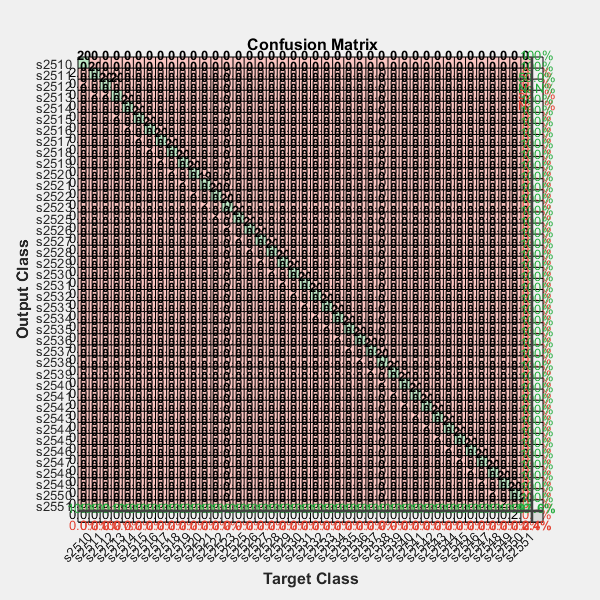


%% Display Confusion Matrix
YPred_Test = classify(net,imdsTest);
figure(1);
plotconfusion(imdsTest.Labels,YPred_Test);

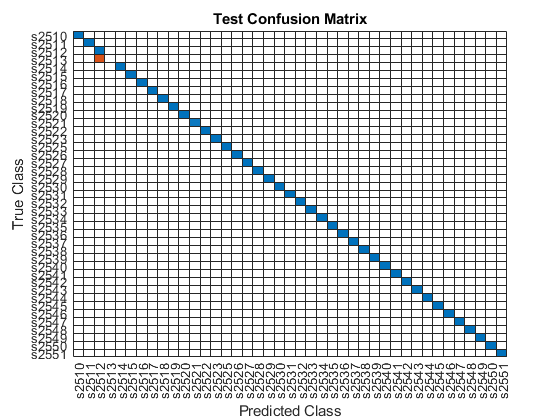

figure(2);
confusionchart(imdsTest.Labels, YPred_Test);
title('Test Confusion Matrix');